## Visualization of Prediction Results

Creation of plots to visualize the results of the prediction analyses (bar graphs and matrices) 

- Run all scripts in HCP Data Prep and Scripts for HCP - Main Sample 

**1. Visualization of results of the prediction analyses of the internally cross-validated Basic and Expanded NMA models in a matrix**

1.1. Retrieve the results from the predictive analyses

matrix = [-.0116, -.0267, .0691, -.0129, .0552;
          .0067, .0293, .0317, -.0605, .0004;
          -.0422, .0462, .1029, -.0300, .0452;
          .0281, .0804, .0708, .0648, .0416;
          -.0148, .0185, .0792, -.0266, .0313;
          .0375, -.0779, .0829, .0133, .0253;
          .0802, .0676, .0744, -.0607, .0847;
          .0633, .0522, .0936, .0631, .0318;
          .0419, .0632, .1362, .0185, .0636]


1.2. Create Colormap

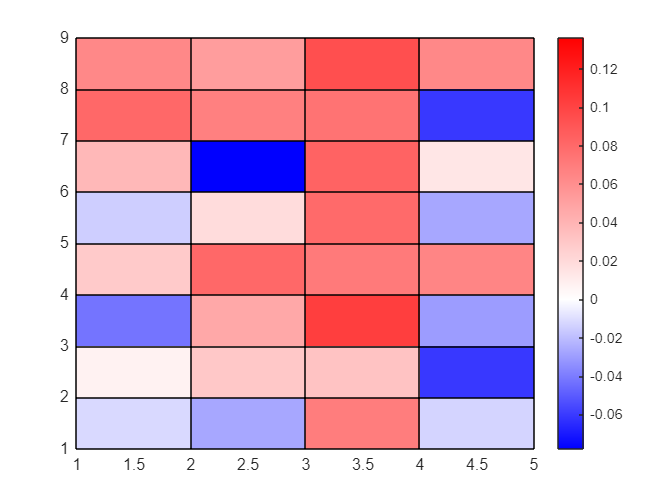

L = 45;             %number of datapoints
data = matrix; % input data 

indexValue = 0;     % value for which to set a particular color
topColor = [1 0 0];         % color for maximum data value (red = [1 0 0])
indexColor = [1 1 1];       % color for indexed data value (white = [1 1 1])
bottomcolor = [0 0 1];      % color for minimum data value (blue = [0 0 1])

% Calculate where proportionally indexValue lies between minimum and
% maximum values

largest = max(max(data));
smallest = min(min(data));
index = L*abs(indexValue-smallest)/(largest-smallest);

% Create color map ranging from bottom color to index color
% Multipling number of points by 100 adds more resolution
customCMap1 = [linspace(bottomcolor(1),indexColor(1),100*index)',...
            linspace(bottomcolor(2),indexColor(2),100*index)',...
            linspace(bottomcolor(3),indexColor(3),100*index)'];

% Create color map ranging from index color to top color
% Multipling number of points by 100 adds more resolution
customCMap2 = [linspace(indexColor(1),topColor(1),100*(L-index))',...
            linspace(indexColor(2),topColor(2),100*(L-index))',...
            linspace(indexColor(3),topColor(3),100*(L-index))'];
customCMap = [customCMap1;customCMap2];  % Combine colormaps
colormap(customCMap)
psudo = pcolor(data);
colorbar

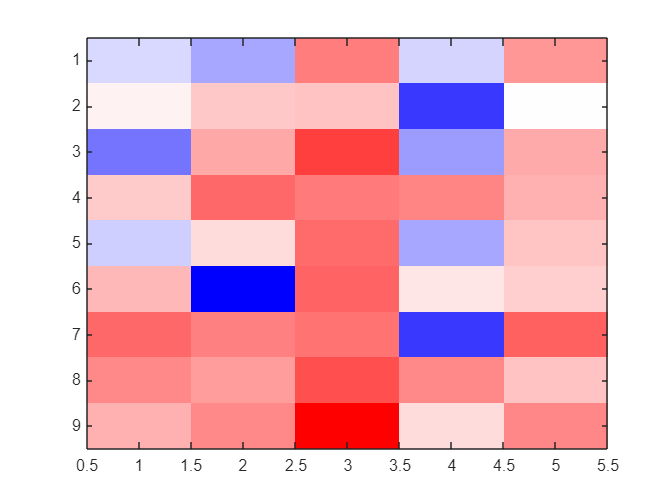

imagesc(data)
colormap(customCMap)

**2. Create the bar plots to compare the prediction performances**

2.1. Comparison of condition-specific predictions (intelligence and personality) 

matrix_all = [.1769,-.0116, -.0264, .0691, -.0129, .0552;
          .1224, .0067, .0293, .0317, -.0605, .0004;
         .1847, -.0422, .0462, .1029, -.0300, .0452;
          .1489, .0281, .0804, .0708, .0648, .0416;
          .0680, -.0148, .0185, .0792, -.0266, .0313;
          .1218, .0375, -.0779, .0829, .0133, .0253;
          .2196, .0802, .0676, .0744, -.0607, .0847;
          .2544, .0633, .0522, .0936, .0631, .0318;
          .2682, .0419, .0632, .1362, .0185, .0636]

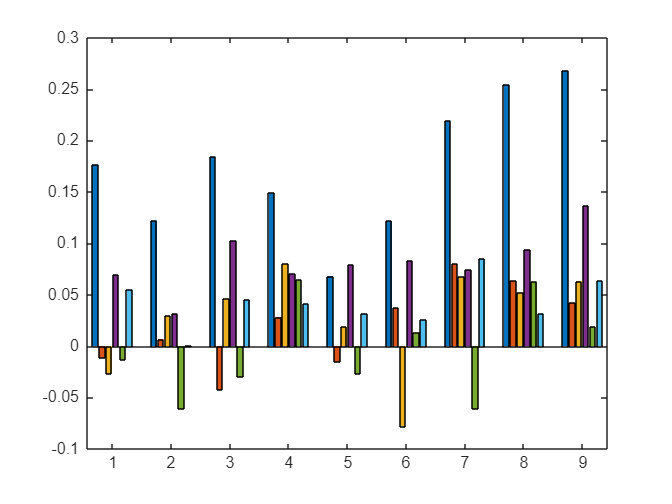

barplot =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


barplot = bar(matrix_all,'GroupWidth',0.7)

2.2. Comparison of personality predictions from rest vs. task-combined personality predictions 

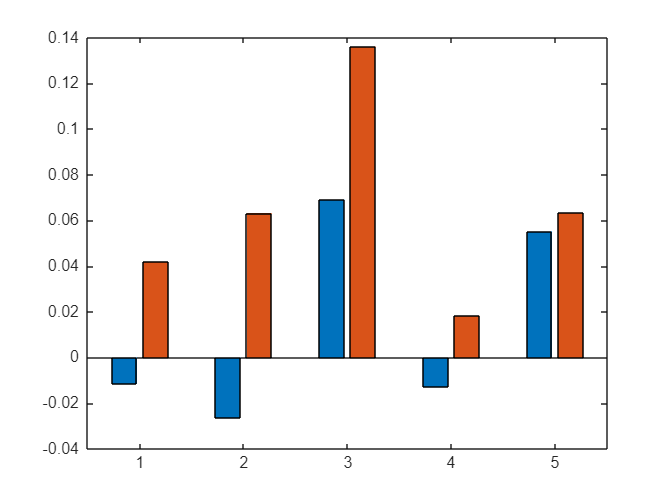

barplot =   1×2 Bar array:

    Bar    Bar


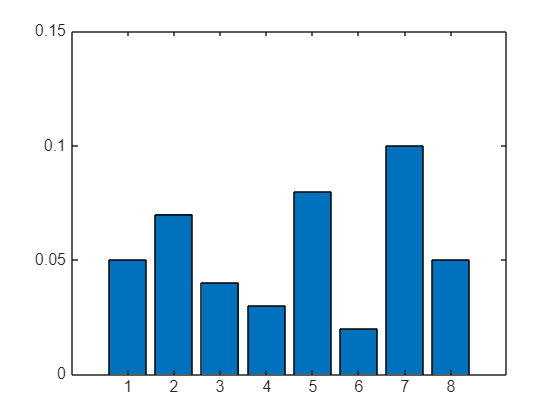


data_rest_task_combined = [-.0116,.0419;
                           -.0264,.0632;
                           .0691,.1362;
                           -.0129, .0185;
                           .0552,.0636]




barplot = bar(data_rest_task_combined,'GroupWidth',0.6)

2.3. Comparison of personality predictions from trait-relevant vs. trait-irrelevant region-specific SC-FC Coupling 

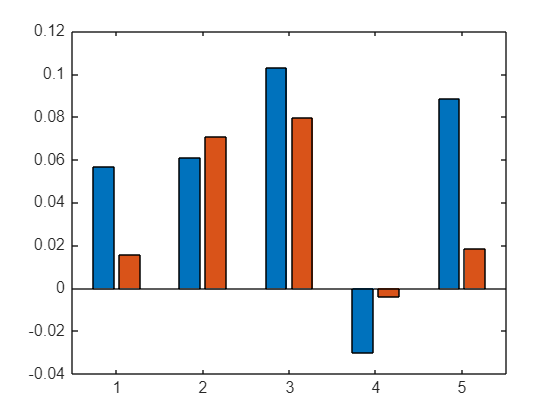

barplot =   1×2 Bar array:

    Bar    Bar


data_trait_relevance = [.0569,.0158;
                        .0610, .0706;
                        .1029, .0795;
                        -.0300, -.0042
                        .0887, .0184]
barplot = bar(data_trait_relevance,'GroupWidth',0.6)